## Program for analysing kinematics of multibody systems

Plan of action:

- Generate input data structure based on the example of slider crank

- Generate constraints and it derivatives (e.g., Newton-Raphson requires constraint vector and it's Jacobian).

- Solve system using NR and advance in time. Store data.

- After solution, make some ilustrative plots.

### Example: slider crank

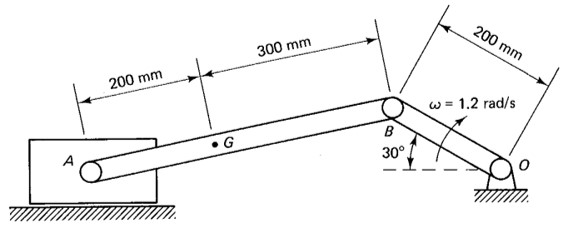

Body numbering

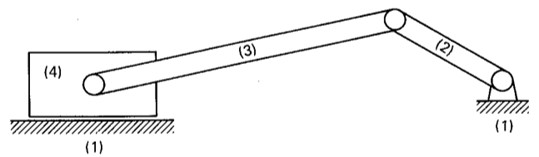

Local coordinate frames

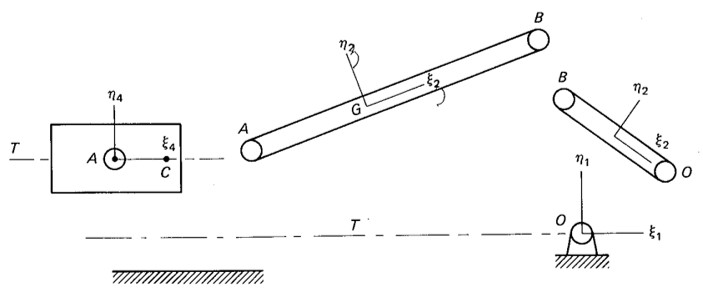

Data from the user

- Bodies and their coordinate frames.

- Joints and their characteristic points

- Solver settings

### Bodies and coordinates

mbs = init_mbs();
mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30),'m', 2.0, 'Ic', 2.0 * 0.2^2 / 12);
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15), 'm', 1.0, 'Ic', 0.5^2 / 12);
mbs = add_body(mbs, "slider", -0.6, 'm', 3.0, 'Ic', 0.1);

### Joints and characteristic points

Vectors that points to joint locations are in local coordinate frame. They do not change locations in time.

mbs = add_revolute(mbs, "revO", "ground", [0; 0], "crank", [0.1, 0.0]);
mbs = add_revolute(mbs, "revB", "crank", [-0.1; 0], "link", [0.3, 0.0]);
mbs = add_revolute(mbs, "revA", "link", [-0.2; 0], "slider", [0.0, 0.0]);

% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);

%Replacing simple joints with translational joint -> tilt the sliding frame
% mbs = add_translational(mbs,"slidertranslation","slider",[0,0],"ground",[0.1,0.1],[-0.1,-0.1],deg2rad(-45));
mbs = add_translational(mbs,"slidertranslation","slider",[0,0],"ground",[0.0,0.0],[0.1,0.1],deg2rad(-45));
% mbs = add_simple_joint(mbs, "slidertranslation", "slider", "y", 0);
% mbs = add_simple_joint(mbs, "sliderrotation", "slider", "fi", 0);

% Driving constraint for the crank
% om = 1.2; % rad/s
% mbs = add_driving_joint(mbs, "crankrotation", "crank", "fi", @(t)-deg2rad(30) - om * t);

### Basic checking

fprintf("System has %d bodies and %d coordinates.\n", length(mbs.bodies), mbs.nq)

System has 4 bodies and 12 coordinates.


fprintf("Number of the joints:\n\tRevolute: %d\n\tPrismatic: %d\n", ...
    length(mbs.joints.revolute), length(mbs.joints.prismatic))

Number of the joints:
	Revolute: 3
	Prismatic: 0


fprintf("\tTranslational: %d\n", length(mbs.joints.translational))

	Translational: 1


fprintf("\tSimple: %d\n\tDriving: %d\n", length(mbs.joints.simple), length(mbs.joints.driving))

	Simple: 3
	Driving: 0


fprintf("In total %d DOF are constrained!\n", mbs.nc)

In total 11 DOF are constrained!


### **Coordinates (initial values)**

They vere defined in the mbs.bodies. We want to put them together in single vector.

q0 = initial_position(mbs);
tic
[q0_correct_NR, NR_iter] = ...
    NR_method(@(y)constraints(mbs, y, 0.0), ...
    @(y)constraints_dq(mbs, y), q0, 1e-8)

q0_correct_NR =    -0.0000
    0.0000
   -0.0000
   -0.0866
    0.0500
   -0.5236
   -0.3622
    0.3330
   -0.8891
   -0.4883


NR_iter = 5

toc

Elapsed time is 0.025266 seconds.


### Forces

mbs = add_gravity(mbs, [0, -9.81]);
mbs=add_rot_spring(mbs, "revO", -deg2rad(30), 1);
mbs=add_rot_damp(mbs, "revO", 0.1);

### Solve EOM

    dq0=q0_correct_NR*0;
    y0=[q0_correct_NR;dq0];
    opts=odeset('RelTol',1e-2,'AbsTol',1e-6);
    alpha=5;
    beta=10;
    t_span=[1 5];
    [t,y]=ode15s(@(t,y) MBS_EOM(t,y,mbs,alpha,beta),t_span,y0,opts);
    q=y(:,1:mbs.nq);
    dq=y(:,mbs.nq+1:end);


### Visualization

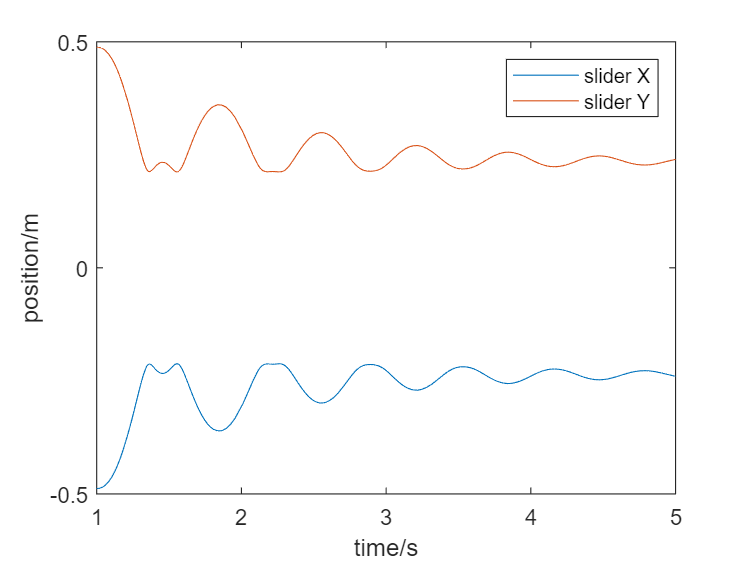

    figure
    plot(t,q(:,10))
    hold on
    plot(t,q(:,11))
    legend('slider X','slider Y')
    xlabel('time/s')
    ylabel('position/m')